clc
data=load('data.txt')

data =     20    25    60    70
    35    30    65   105
    40    34    75   135
    50    37    80   170


% Create a plot of the data
xt=(data);
yt=xt(:);
% Add axis labels and a title

%plot(data');
legend('2012','2013','2014','2015');

%row mean of all the row int he matrix
%the standard deviation and means
row_stds=std(data,1,2);
row_means=mean(data,2);
disp(row_means);

   43.7500
   58.7500
   71.0000
   84.2500



disp(row_stds);

   21.6145
   29.8695
   40.1310
   51.9056



% moindre carree
polyfit(row_means,row_stds,1)

ans =     0.7531  -12.6468


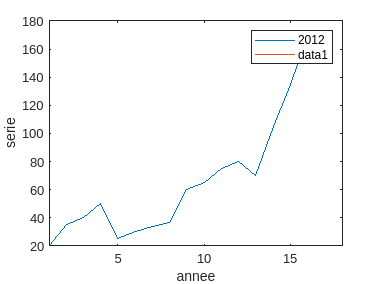

plot(row_means,row_stds)

% k impair
% Define the parameters
k = 7;  % value of k
m = (k-1)/2;  % value of m
T=length(yt);
% Calculate the rolling mean using the formula
pair_rolling_means=zeros(T-k+2,1);
for i=k:T
    t_prime=sum(i-(k-1):i)/k
    pair_rolling_means(i) = (sum(yt(t_prime-m:t_prime+m))) / k;    
end

t_prime = 4

t_prime = 5

t_prime = 6

t_prime = 7

t_prime = 8

t_prime = 9

t_prime = 10

t_prime = 11

t_prime = 12

t_prime = 13

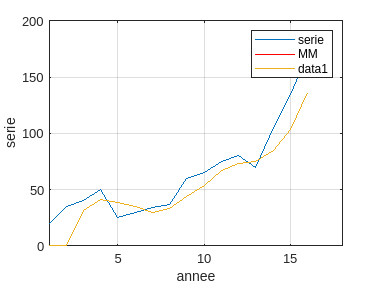

figure
plot(yt);
xlim([1 T+2])
xlabel('annee');
ylabel('serie');
hold on;
x2=k-3:T-3;
plot(x2,rolling_means(k-3:T-3),'r');
legend('serie','MM');
grid on;

plot(rolling_means)


% k pair
% Define the parameters
%pair_k = 4;  % value of k
%pair_m = (pair_k-1)/2;  % value of m
% Calculate the rolling mean using the formula
%pair_rolling_means=zeros(T-pair_k+2,1);
%for i=k:T-1
 %   t_prime=(0.5*(i-1)+i+(i+1)*0.5)/k
    %pair_rolling_means = (sum(yt(t_prime-pair_m+1:t_prime+pair_m))) / k;   
%end
%plot(rolling_means)


